# Lattice characterization

expt_bag_path = "lattice_calibration_data/15x15x15/trial1/lattice_data_1";
system("~/colcon_ws/install/setup.bash");

/bin/bash: line 1: /home/barracuda/colcon_ws/install/setup.bash: Permission denied


bag = ros2bagreader(expt_bag_path); 
bag_info = ros2("bag","info",expt_bag_path);

filtered data

tf_bag = select(bag,"Topic",{"/tf"});
tf_static_bag = select(bag,"Topic",{"/tf_static"});
ft_bag = select(bag,"Topic",{"/nano_17_proxy/ft"});
tf_data = readMessages(tf_bag);
tf_static_data = readMessages(tf_static_bag);
ft_data = readMessages(ft_bag);

start_time = bag.StartTime;
end_time = bag.EndTime;
frames = bag.AvailableFrames;
transform = getTransform(bag,"left_tool0","world",ros2time(start_time+50));
transform.transform.translation.z;

% now get the ft values and time
fz = ft_data{1}.data(4);
timestamp = ft_data{1}.data(1);
corresponding_transform = getTransform(bag,"left_tool0","world",ros2time(timestamp));
corresponding_z = corresponding_transform.transform.translation.z;

% make t vector, fz vector, z vector, z' vector
dim = size(ft_data);
n = dim(1,1);

t = zeros(n,1,"double");
fz = zeros(n,1,"double");
z = zeros(n,1,"double");
z_v = zeros(n,1,"double");

for i = 1:n
    t(i,1) = ft_data{i}.data(1);
    fz(i,1) = ft_data{i}.data(4);

    is_available = canTransform(bag,"left_tool0","world",t(i));
    if is_available
        current_transform = getTransform(bag,"left_tool0","world",t(i,1));
        z(i,1) = current_transform.transform.translation.z;
    else
        disp("Break at : ")
        i
        disp("Total its : ")
        n
        break
    end
end

Break at : 


i = 6267

Total its : 


n = 6268

z = z-z(1,1);

t(i:n) = [];
fz(i:n) = [];
z(i:n) = [];
z_v(i:n) = [];

% crop the starting as well till 10s
t(1:420) = [];
fz(1:420) = [];
z(1:420) = [];
z_v(1:420) = [];

% crop the starting as well till 10s
t(end-420:end) = [];
fz(end-420:end) = [];
z(end-420:end) = [];
z_v(end-420:end) = [];

% this for plotting
t_adjusted = t-t(1,1);

% need to find z_v
n_new = size(t_adjusted);
n_new = size(1,1);

z_v(1,1) = 0.0;
z_v(n_new,1) = 0.0;

for i=2:n_new-1
    z_v(i) = (z(i+1) - z(i-1))/(t_adjusted(i+1)-t_adjusted(i-1,1));
end

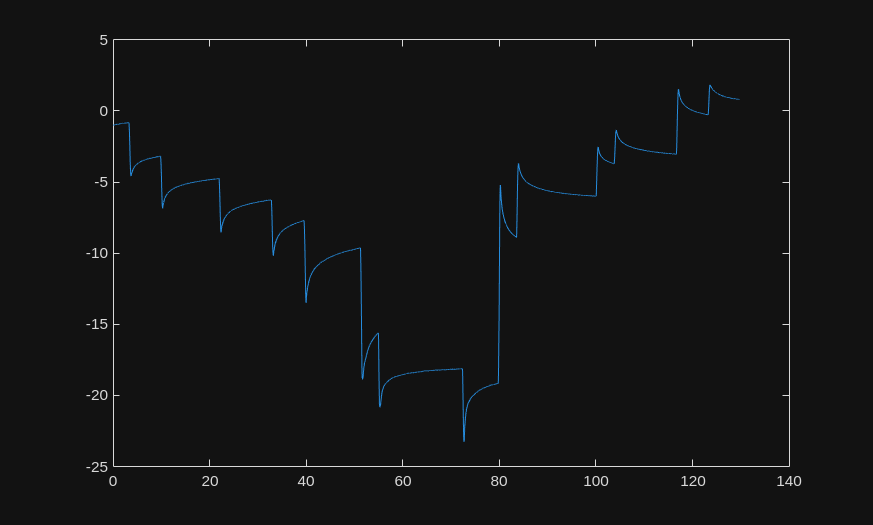

% now we have t,fz,z,z_v
% plot everything 
plot(t_adjusted,fz);

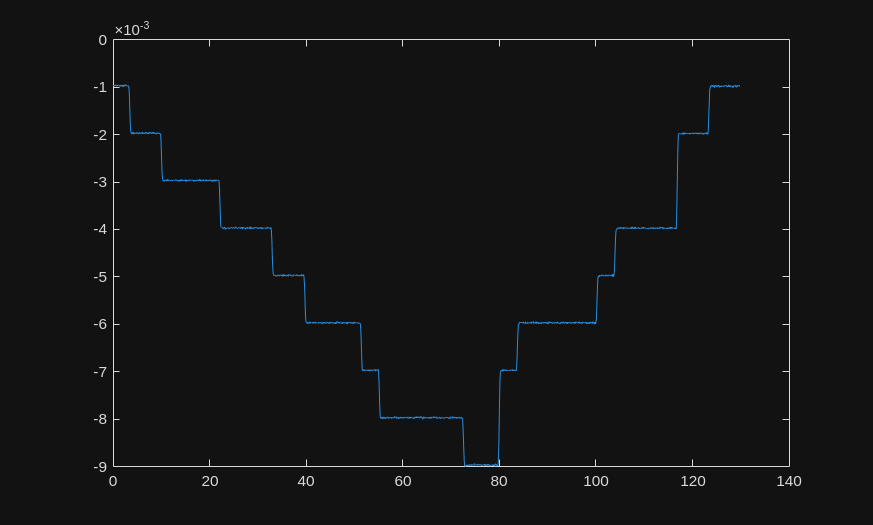

plot(t_adjusted,z);

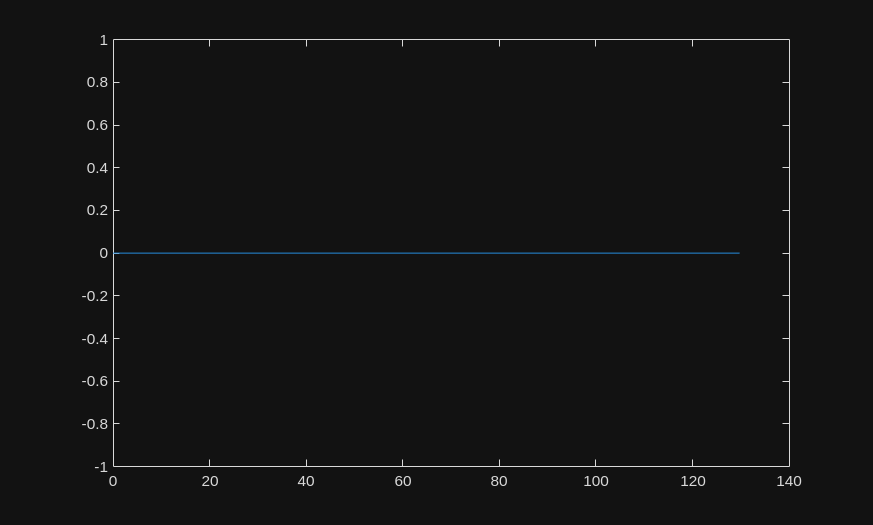

plot(t_adjusted,z_v);

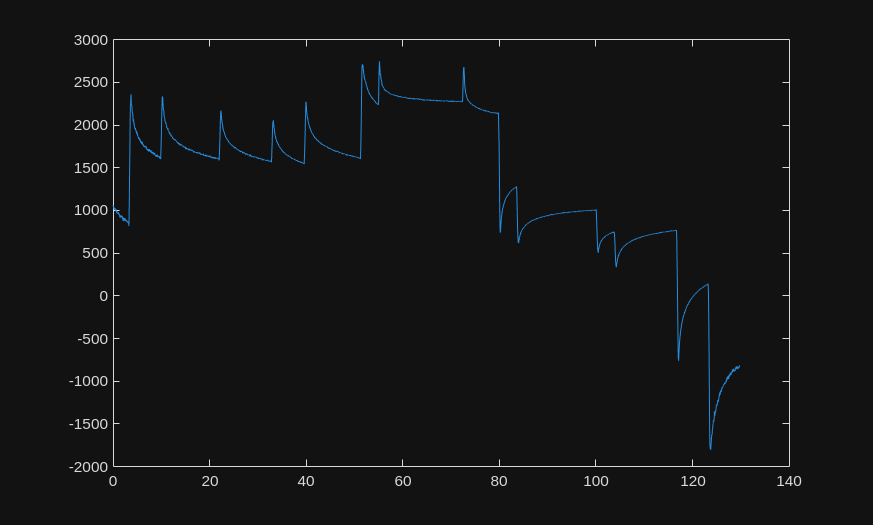

elasticity = fz./z;
plot(t_adjusted,elasticity)

length = size(t_adjusted);
length = length(1,1);
delta_t = zeros(length,1,"double");
delta_t(1) = 0;
for i=2:length
    delta_t(i) = t_adjusted(i) - t_adjusted(i-1);
end
delta_t = mean(delta_t)

delta_t = 0.0239

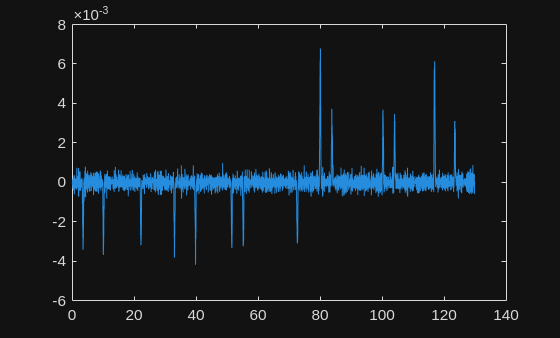


delta_z = zeros(length,1,"double");
delta_z(1) = 0;
delta_z(length) = 0;
for i=2:length-1
    delta_z(i) = (z(i+1) - z(i-1))/2;
end

z_v = delta_z/delta_t;
plot(t_adjusted,z_v);